# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `layers`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 20-Nov-2023 04:25:54

## Load Initial Parameters

Load parameters for network initialization. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("D:\lxh\result\1120\alexnet_1120_01.mat");

## Import Data

Import training and validation data.

imdsTrain = imageDatastore("D:\lxh\dataset\train_single\enhancement_images","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7);

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([227 227 3],imdsTrain);
augimdsValidation = augmentedImageDatastore([227 227 3],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",6e-05,...
    "MaxEpochs",100,...  % 設置最大訓練迭代次數
    "Shuffle","every-epoch",...
    "Plots","training-progress",... % 顯示訓練進度圖表
    "ValidationData",augimdsValidation,... % 驗證集數據
    'ValidationFrequency', 5,...  % 每5個迭代計算一次驗證集性能
    'Verbose', true,...  % 顯示訓練信息
    'OutputFcn', @(info)stopIfValidationLossStops(info, 10)); % 設置回調函數(早停法，須設定耐心值（patience）比如10)

## Create Array of Layers

layers = [
    imageInputLayer([227 227 3],"Name","data","Mean",trainingSetup.data.Mean)
    convolution2dLayer([11 11],96,"Name","conv1","BiasLearnRateFactor",2,"Stride",[4 4],"Bias",trainingSetup.conv1.Bias,"Weights",trainingSetup.conv1.Weights)
    reluLayer("Name","relu1")
    crossChannelNormalizationLayer(5,"Name","norm1","K",1)
    maxPooling2dLayer([3 3],"Name","pool1","Stride",[2 2])
    groupedConvolution2dLayer([5 5],128,2,"Name","conv2","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.conv2.Bias,"Weights",trainingSetup.conv2.Weights)
    reluLayer("Name","relu2")
    crossChannelNormalizationLayer(5,"Name","norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2","Stride",[2 2])
    convolution2dLayer([3 3],384,"Name","conv3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.conv3.Bias,"Weights",trainingSetup.conv3.Weights)
    reluLayer("Name","relu3")
    groupedConvolution2dLayer([3 3],192,2,"Name","conv4","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.conv4.Bias,"Weights",trainingSetup.conv4.Weights)
    reluLayer("Name","relu4")
    groupedConvolution2dLayer([3 3],128,2,"Name","conv5","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.conv5.Bias,"Weights",trainingSetup.conv5.Weights)
    reluLayer("Name","relu5")
    maxPooling2dLayer([3 3],"Name","pool5","Stride",[2 2])
    fullyConnectedLayer(4096,"Name","fc6","BiasLearnRateFactor",2,"Bias",trainingSetup.fc6.Bias,"Weights",trainingSetup.fc6.Weights)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(4096,"Name","fc7","BiasLearnRateFactor",2,"Bias",trainingSetup.fc7.Bias,"Weights",trainingSetup.fc7.Weights)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(2,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Train Network

Train the network using the specified options and training data.

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       53.12% |       50.00% |       2.0332 |       1.8702 |      6.0000e-05 |
|       2 |           5 |       00:00:12 |       49.22% |       61.90% |       1.2555 |       0.7031 |      6.0000e-05 |
|       4 |          10 |       00:00:23 |       66.41% |       71.43% |       0.8673 |       0.5531 |      6.0000e-05 |
|       5 |          15 |       00:00:35 |       70.31% |       76.79% |       0.7271 |   

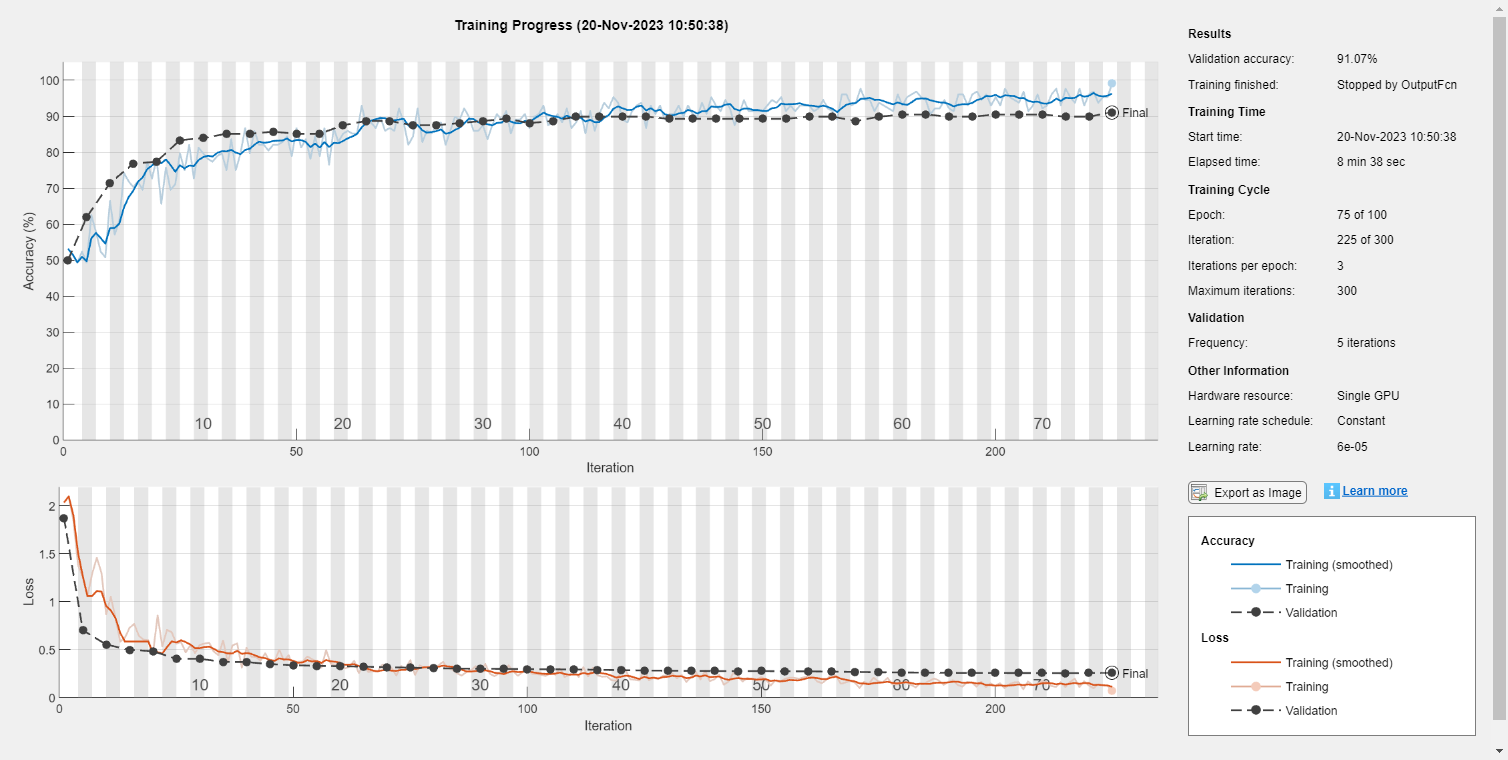

[net, traininfo] = trainNetwork(augimdsTrain,layers,opts);

# **早停法**

function stop = stopIfValidationLossStops(info, patience)
    % 檢查驗證損失是否停滯不前
    persistent count;
    persistent bestLoss;

    stop = false;

    if info.State == "start"
        count = 0;
        bestLoss = inf;
    elseif info.State == "iteration"
        % 檢查每次迭代的驗證損失
        currentLoss = info.ValidationLoss;

        if currentLoss < bestLoss
            bestLoss = currentLoss;
            count = 0;  % 重置計數
        else
            count = count + 1;
        end

        % 如果驗證損失停滯不前，則增加計數
        if count >= patience
            fprintf('Validation loss has not improved for %d epochs. Stopping training.\n', patience);
            stop = true;
        end
    end
end